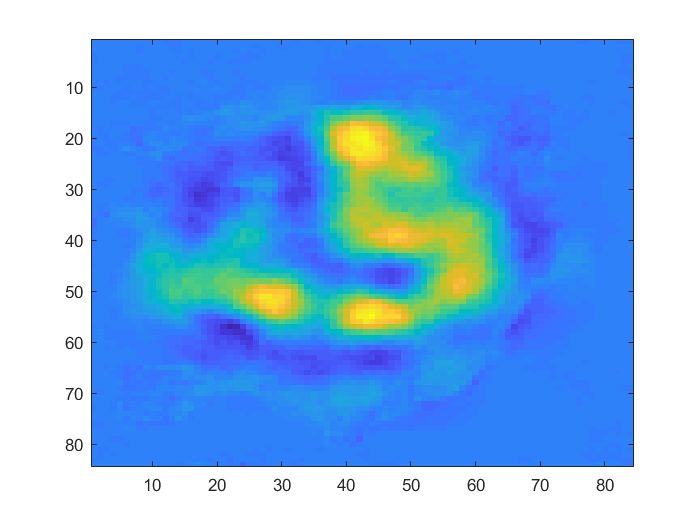

clear
global  txt
root = 'D:\study\PatternDL\python\data\';
modelName = 'Net_Layers2_pink_beta003_kernel8x8';
PatternPython = readNPY([root, modelName,'\Patterns.npy']);
Ipython = readNPY([root, modelName,'\Intensity.npy']);
PmeanPython = readNPY([root, modelName,'\Pmean.npy']);
CGIpython = readNPY([root, modelName,'\CGI_img.npy']);
PIpython = readNPY([root, modelName,'\PI.npy']);
img_ori =double( imresize(imread([root,'check_pic\and.jpg']),[84,84]) );
% imgOriSize = size(img_ori);
% if(imgOriSize(3)==3)
%     img_ori = rgb2gray(img_ori);
% end
img_ori = readNPY([root, modelName,'\input_image.npy']);
PatternPython = (PatternPython);
txtSize = size(PatternPython);
PatternPython = reshape(PatternPython(1,:,:,:),txtSize(2:end));
img_ori  = reshape(img_ori,txtSize(3:end));
txt = zeros([txtSize(3:4),txtSize(2)]);
for ii = 1:txtSize(2)
    txt(:,:,ii) = PatternPython(ii,:,:);
%     imagesc(txt(:,:,ii))
end

[CGIimageMatlab,Imatlab,PmeanMatlab,PImeanMatlab] = generateCGI(img_ori,0.01,84,84);
imagesc(PImeanMatlab-PmeanMatlab.*mean(Imatlab))

PmeanPython = reshape(PmeanPython,size(PmeanMatlab));
PIpython = reshape(PIpython,size(PmeanMatlab));
CGIpython = reshape(CGIpython,[84,84]);

a = Imatlab - Ipython;
max(a(:))

ans = single
60.7782



max(CGIimageMatlab(:))

ans = 5.6528

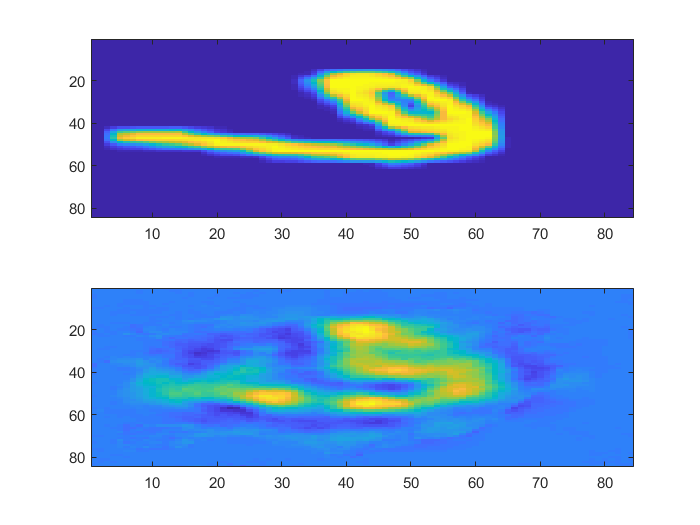

subplot(2,1,1)
imagesc(img_ori)
subplot(2,1,2)
imagesc(CGIimageMatlab)